clear;
close all;

XTrain = load('H:\rest_tremor\segment\origin\features.mat').feat;
% YTrain = categorical(load('H:\rest_tremor\segment\Fifteenseg\labels.mat').seg_labels);
YTrain = categorical(importdata('H:\rest_tremor\segment\origin\label.xlsx'));
YTrain = YTrain(:,2);

XTrain2 = XTrain(1:110,1);  % 128 dim
YTrain2 = YTrain(1:110);
XValid = XTrain(111:128,1);
YValid = YTrain(111:128);

inputSize = 10;  % Sequence input with 10 dimensions
% numHiddenUnits = 1000;
numClasses = 129;

layers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(5000,'OutputMode','sequence')
    bilstmLayer(3000,'OutputMode','sequence')
    bilstmLayer(1000,'OutputMode','sequence')
    bilstmLayer(200,'OutputMode','last')
    fullyConnectedLayer(numClasses,"BiasInitializer","narrow-normal")
    softmaxLayer
    classificationLayer]

layers =   具有以下层的 8x1 Layer 数组:

     1   ''   序列输入    序列输入: 10 个维度
     2   ''   BiLSTM    BiLSTM: 5000 个隐含单元
     3   ''   BiLSTM    BiLSTM: 3000 个隐含单元
     4   ''   BiLSTM    BiLSTM: 1000 个隐含单元
     5   ''   BiLSTM    BiLSTM: 200 个隐含单元
     6   ''   全连接     129 全连接层
     7   ''   Softmax   softmax
     8   ''   分类输出    crossentropyex

maxEpochs = 100;
miniBatchSize = 4;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','gpu', ...
    'ValidationData',{XValid,YValid}, ...
    'ValidationFrequency',10, ...
    'GradientThreshold',1, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest', ...
    'Shuffle','never', ...
    'Verbose',0, ...
    'Plots','training-progress');

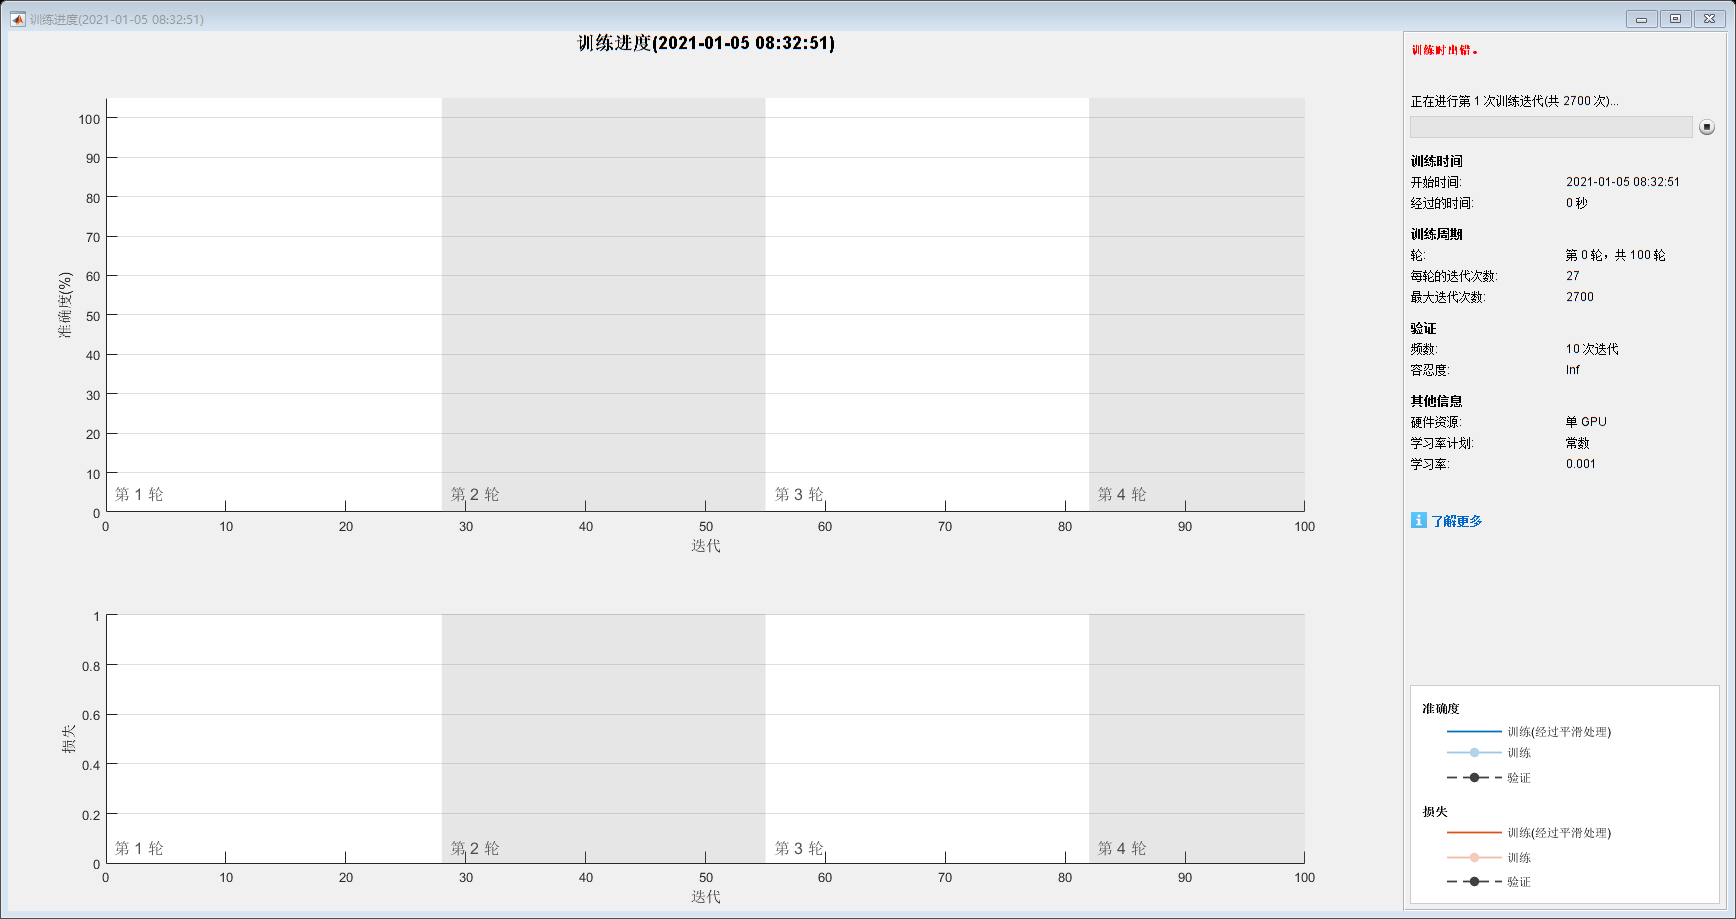

错误使用 trainNetwork (line 170)
GPU 内存不足。请尝试使用 trainingOptions 函数减小 'MiniBatchSize'。

原因:
    错误使用 nnet.internal.cnngpu.biLSTMForwardTrain
    Out of memory on device. To view more detail about available memory on the GPU, use 'gpuDevice()'. If the problem persists, reset the GPU by calling 'gpuDevice(1)'.

net = trainNetwork(XTrain2,YTrain2,layers,options);